[sheet,str]=xlsread('E:\code\meisai\source\Problem_C_Data_Wordle_5.xlsx');

sheet是读入的excel表格的数字，str是单词

figure(1)
trydistribution=sheet(:,5:11);
Sum=sum(trydistribution,2);
data1 = betarnd(4,3,100,1);
MERGE_SORT(data1,1,length(data1));
[p,ci] = betafit(data1,0.01)

p =     4.8573    3.6931


ci =     3.2762    2.6019
    7.2015    5.2421


x=0:0.01:1;
y=betapdf(x,p(1,1),p(1,2))

y =          0    0.0000    0.0001    0.0002    0.0007    0.0016    0.0032    0.0056    0.0091    0.0139    0.0203    0.0285    0.0386    0.0510    0.0658    0.0832    0.1034    0.1264    0.1526    0.1818    0.2143    0.2501    0.2892    0.3315    0.3772    0.4260    0.4780    0.5330    0.5909    0.6516    0.7148    0.7803    0.8480    0.9175    0.9886    1.0610    1.1344    1.2085    1.2830    1.3574    1.4315    1.5049    1.5772    1.6480    1.7170    1.7838    1.8480    1.9092    1.9672    2.0215


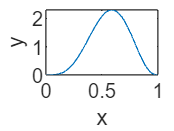

plot(x,y);
xlabel('x');
ylabel('y');

figure(3);
TF = issorted(data1,1)

TF = logical
   0


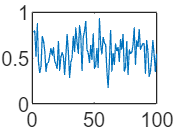

plot(data1);

u = 0

p =     0.0135    0.0694


ci =     0.0120    0.0399
    0.0151    0.1206


y =          0    0.7884    0.7959    0.8003    0.8035    0.8060    0.8081    0.8099    0.8115    0.8129    0.8141    0.8153    0.8164    0.8174    0.8183    0.8192    0.8200    0.8208    0.8216    0.8223    0.8230    0.8236    0.8243    0.8249    0.8255    0.8261    0.8267    0.8272    0.8278    0.8283    0.8288    0.8293    0.8298    0.8303    0.8308    0.8313    0.8318    0.8322    0.8327    0.8332    0.8336    0.8341    0.8345    0.8349    0.8354    0.8358    0.8362    0.8367    0.8371    0.8375


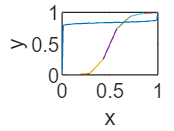

for i=44:44%length (trydistribution)
    u=0
    cnt=0;
    figure(2)
    for j=1:7
        next=cnt+trydistribution(i,j);
        k=trydistribution(i,j)/Sum(i,1)*7;
        for hh=1:10
            u=u+1;
            c(u)=hh/70*k+cnt/Sum(i,1);
        end
        plot([(j-1)/7,j/7],[cnt/Sum(i,1),next/Sum(i,1)]);
        hold on;%保持在图形中
        cnt=next;
    end
    [p,ci] = betafit(c(1,1:70),0.05)
    x=0:0.01:1;
    y=betacdf(x,p(1,1),p(1,2))
    plot(x,y);
    xlabel('x');
    ylabel('y');
    xlabel('x');
    ylabel('y');
end